clc;
clear;

Calculando o Tau e o Kcc

opts = detectImportOptions('dados_aquecedor_matlab.csv');
T = readtable('dados_aquecedor_matlab.csv', opts);
time = T.time;
temp_offset = T.temp_offset;

% Achando tau e o ganho Kcc
stable_temperature = 26.0;
aux_temp = stable_temperature * 0.632; 
[~, idx] = min(abs(temp_offset - aux_temp));
tau = time(idx);
Kc = stable_temperature/0.015;
disp(['Tau: ', num2str(tau)]);

Tau: 930


disp(['Kcc: ', num2str(Kc)]);

Kcc: 1733.3333


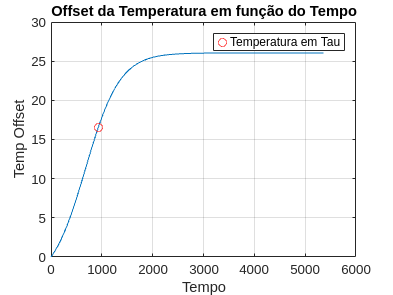



plot(time, temp_offset);
hold on;
temp_offset_at_tau = temp_offset(idx);
plot(tau, temp_offset_at_tau, 'ro'); % Destacar o ponto
title('Offset da Temperatura em função do Tempo');
legend('', 'Temperatura em Tau');
xlabel('Tempo');
ylabel('Temp Offset');
grid on;
hold off;

Achando a função de transferencia

s = tf('s');

% Kcc = Resistencia Termica
% Tau = Resistencia Termica * Capacitancia Termica
G = Kc / (tau*s + 1)


G =
 
    1733
  ---------
  930 s + 1
 
Continuous-time transfer function.
Model Properties


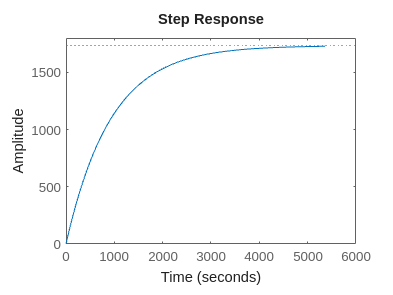

step(G, time);

Aplicando o Ganho da Potencia Elétrica pelo relé e Ganho Kph

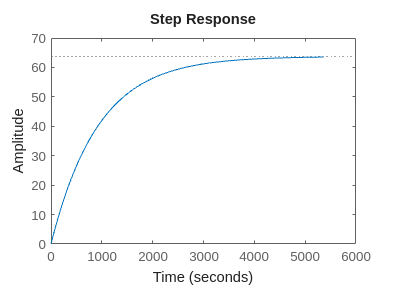

Kcc = 127^2/6.5; % chechar no atigo ganho do rele
Kr = 1/16.129;
Kph = 2.39 * 10^(-4);
K = Kcc * Kr * Kph;
step(K * G, time);

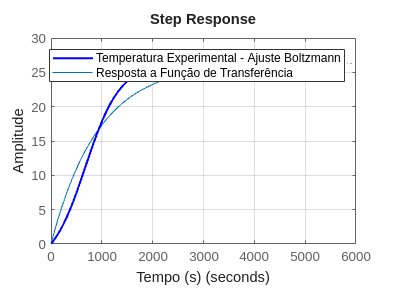


H =
 
      63.73
  -------------
  930 s + 64.73
 
Continuous-time transfer function.
Model Properties


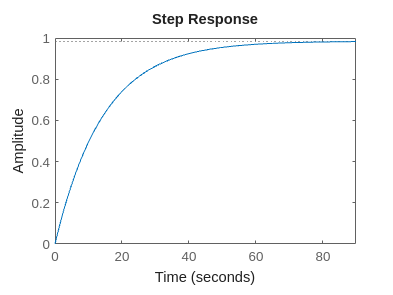


figure;
plot(time, temp_offset, 'b', 'LineWidth', 1.5); % Plota o sinal contínuo
hold on;
Kpe = 32^2 / 16.129;
step(Kpe * Kph * G, time);
hold off;

xlabel('Tempo (s)');
ylabel('Amplitude');
title('Step Response');
legend('Temperatura Experimental - Ajuste Boltzmann', 'Resposta a Função de Transferência');
grid on;

Aplicando o controlador

Para reduzir o tempo de assentamento em 50%, precisamos dobrar a velocidade do sistema. O tempo de assentamento original é **57.48s**, e queremos que seja **28.74s**.

O tempo de assentamento de um sistema de **1ª ordem** é aproximadamente:

Ts=4τ

Onde τ\tau é a constante de tempo do sistema. A equação em malha fechada tem τ=14.37. Para atingir o novo tempo de assentamento, precisamos que:

τnovo=14.37/2 = 7.19

Para isso, aplicamos um **controlador PD**:

C(s)=Kp(1+Tds)

**Cálculo dos parâmetros:**

- **Ganho proporcional (****K****p)**Ajustamos Kp para atingir τnovo: Kp=930/(7.19×64.73)≈2.06

- **Ganho derivativo (****T****d)**Um valor típico é **10% da nova constante de tempo**:Td≈0.1×7.19=0.72

**Controlador final:**C(s)=2.06(1+0.72s)

Kp� = 2.06;
Td = 0.72;


C =
 
  1.483 s + 2.06
 
Continuous-time transfer function.
Model Properties


C=Kp*(1+Td*s)


sistema_controlado =
 
  94.53 s + 131.3
  ---------------
  1025 s + 132.3
 
Continuous-time transfer function.
Model Properties


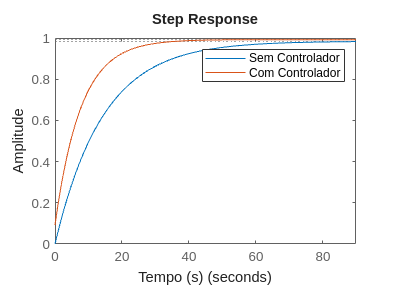

sistema_controlado = feedback(K * G * C, 1)

figure;
step(H);
hold on;
step(sistema_controlado);
hold off;
xlabel('Tempo (s)');
ylabel('Amplitude');

legend('Sem Controlador', 'Com Controlador');

